%clearing crap 
clear all
clf

%reading data (including strings)
%data = readcell("temp_data_230623.csv","NumHeaderLines",1);
%data = readcell("air_temp_data_250623.csv","NumHeaderLines",1);
data = readcell("165_205_temp_data_250623.csv","NumHeaderLines",1);
time = data(1:height(data),1);
time = string(time);

%%%correcting for anomalous 50 x tick
time(any(time=="50", 2), :) = []; %removing "50" value from time array


%extracting column headers
%data = readtable("temp_data_230623.csv");
%data = readtable("air_temp_data_250623.csv");
data = readtable("165_205_temp_data_250623.csv");

colnames=data.Properties.VariableNames; %col names

nrows = height(data); %extracting number of rows
ncols = width(data); %extracting number of columns

data_array = table2array(data(1:nrows,2:ncols)); %converting table2array

%%%correcting for anomalous 50 x tick
temp_time = 0:nrows-1; %if no annomalous 50

temp_time =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17


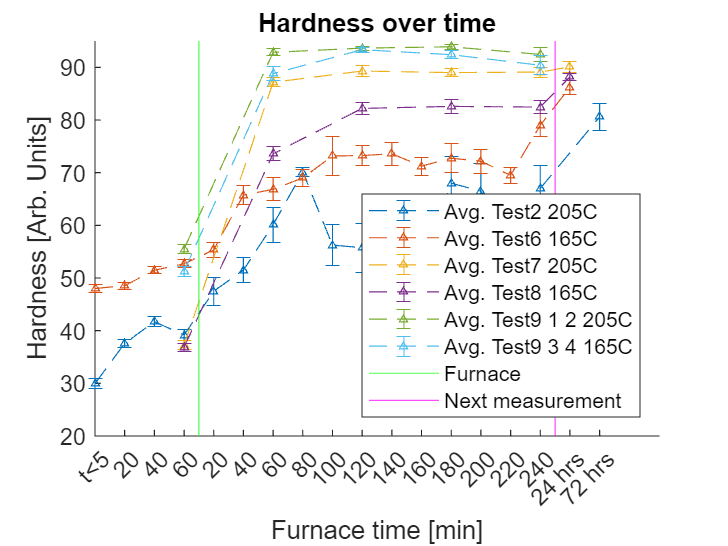

% temp_time = 0:nrows-2;
% temp_time = [temp_time(1:3) 2.5 temp_time(4:end)];
temp_time = transpose(temp_time);

%looping through all rows
for n=1:(ncols-1)/2
    
    %extracting plot data
    plot_data = cat(2,temp_time,data_array(1:nrows,(n-1)*2+1),data_array(1:nrows,(n-1)*2+2));

    %removing rows containign NaN
    plot_data(any(isnan(plot_data), 2), :) = [];

    %extracting name
    name = string(colnames((n-1)*2+2));
    name = strrep(name,"_"," "); %removing underscores
    name = strrep(name,"Avg","Avg."); %removing underscores

    %perfomring plot
    errorbar(plot_data(1:length(plot_data),1),plot_data(1:length(plot_data),2), plot_data(1:length(plot_data),3), "^--",'MarkerSize',3,'DisplayName',name)
    hold on %plotting all values on same graph
    
end

%setting desired labels
temp_time(any(temp_time==2.5, 2), :) = [];%removing rows containign NaN
xticks(temp_time)
time = cellstr(transpose(time));
xticklabels(time)

hold off %end of plotting
%adding legend
legend show
legend("location","southeast")

%setting x & y limits
xlim([0 nrows+1])
ylim([20 95])

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

%labelling graph
xlabel("Furnace time [min]");
ylabel("Hardness [Arb. Units]");
title("Hardness over time")

%adding x lines
xline(3.5,"g","DisplayName","Furnace")
xline(15.5,"m","DisplayName","Next measurement")